**Question 1**

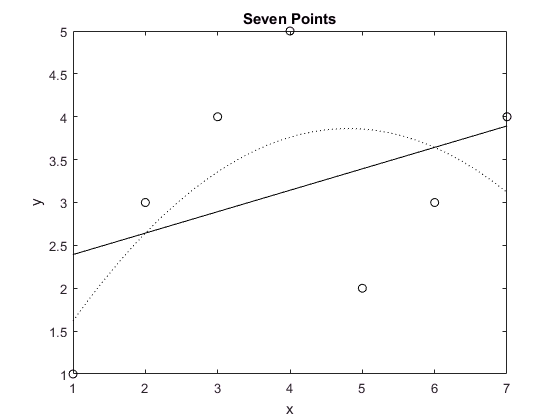

%(1)
t=readtable('E001.csv');
%(2)
plot(t.x,t.y,'ko');
%(3)
hold on;
p01=polyfit(t.x,t.y,1);
x0=sort(t.x);
plot(x0, polyval(p01,x0),'k-');
%(4)
p02=polyfit(t.x,t.y,2);
x1=linspace(min(t.x), max(t.x), 30);
plot(x1, polyval(p02,x1),'k:');
%(5)
xlabel('x');
ylabel('y');
title('Seven Points');

**Question 2**

%%(1)
rng(123456);
%%(2)
x=[randn(4,4) rand(4,4)];
%%(3)
x(2,:)=x(3,:).^2+2*x(1,:);
%%(4)
s=sort(sum(x, 1), 'descend');
%%(5)
Q02=s(end-1)

Q02 = -2.3670

**Question 3**

%(2)
V=13.7;
S=100;
K=95;
r=0.1;
T=0.25;
f=@(x) Q03fun(S,K,r,T,x)-V;
Q03sigma=fsolve(f,0.8)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Q03sigma = 0.5003

**Question 4**

H=[6 4;4 2];
f=[1; 6];
Aeq=[];
beq=[];
A=[-2 -3];
b=[-4];
lb=[0 0];
ub=[];
[w, fval]=quadprog(H, f, A, b, Aeq, beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

Q04.min = fval-2

Q04 =     min: 7.7778
      x: 3.9310e-08
      y: 1.3333

Q04.x=w(1)

Q04 =     min: 7.7778
      x: 3.9310e-08
      y: 1.3333

Q04.y=w(2)

Q04 =     min: 7.7778
      x: 3.9310e-08
      y: 1.3333